# Demo: how to use `FEMA_fit`

This demo shows how to use the `FEMA_fit` function to fit linear mixed-effects models

First, we simulate a dataset; next, we fit the model and estimate the parameteres; then, we visualize how the estimated values are correlated to the simulated ground truth values. Finally, there is a showcase of additional ways of calling `FEMA_fit` towards the end.

## Requirements

Please modify this paths to where you have downloaded the FEMA toolbox; if you already have FEMA on your MATLAB path, then this step is not required

addpath(genpath('/Applications/Projects/2025-11-28_FEMA-Demo/cmig_tools-main'))

## Create simulated dataset

%% Setup parameters 
nObservations    = 25000;
nXvars           = 50;
nyVars           = 50;
nFamMembers      = 4; % up to four members in a family
nRepObservations = 4; % up to four repeated measurements
RandomEffects    = {'F', 'S', 'E'}; 
epsmin           = 0.2; 
sigmaLow         = 0.2;

%% Control random number here and generate ground truth effect sizes
rng(20251130, 'twister');

% Beta is uniformally distributed in the range -0.02 and 0.02 => rand
betaLow  = -0.2;
betaHigh = 0.2;
betaTrue = betaLow + (betaHigh-betaLow).*rand(nXvars,nyVars);

% Random effects are uniformally distributed in the range 0.2 and 0.8
% Note that the range is the sum of F and S and does not imply that each of
% the F and S values will be at least equal to 0.2
sig2mat_true = NaN(length(RandomEffects)-1, nyVars); 
ivec         = 1:nyVars;
while ~isempty(ivec)
    sig2mat_true(:,ivec) = rand([size(sig2mat_true,1) length(ivec)]);
    cond                 = (sum(sig2mat_true,1) >= sigmaLow) & ...
                           (sum(sig2mat_true,1) < 1-epsmin);
    ivec                 = find(not(cond));
    if isempty(ivec)
        break;
    end
end
sig2mat_true = cat(1, sig2mat_true, 1-sum(sig2mat_true,1));

% Total residual variance is 1
sig2tvec_true = 1;

% Generate individual IDs
iid_int = sort(repmat(1:nObservations, 1, nRepObservations));

% Generate family IDs
fid_int = ceil(iid_int / nFamMembers);

% Using dec2base: zero prefixes shouldn't matter
iid = cellstr([repmat('I', length(iid_int),1), dec2base(iid_int,10)]);
fid = cellstr([repmat('F', length(fid_int),1), dec2base(fid_int,10)]);
clear('iid_int'); clear('fid_int');

% Generate event IDs
allEvents = (1:nRepObservations)';
eid       = repmat(allEvents, nObservations, 1);

% Now, annihilate vists
toKeep   = randperm(length(iid), nObservations);
toDelete = setdiff(1:length(iid), toKeep);
eid(toDelete) = [];
iid(toDelete) = [];
fid(toDelete) = [];
    
% Initialize a few additional variables
agevec = zeros(nObservations, 1);
y_RFX  = nan(nObservations, nyVars);

% Generate X variables: X is normally distributed => randn
% Make the first X variable as the intercept
X     = [ones(nObservations,1), randn(nObservations, nXvars-1)];
y_FFX = X * betaTrue;

% Parse family structure
clusterinfo = FEMA_parse_family(iid, eid, fid, agevec, [], 'RandomEffects', RandomEffects);

03-Dec-2025 09:20:29 in FEMA_parse_family - Parsing family structure


% Generate y_RFX
nfam = length(clusterinfo);
for fi = 1:nfam
    tmp = 0;
    for ri = 1:length(RandomEffects)
        tmp = tmp + sqrt(sig2mat_true(ri,:)) .*                        ...
                    mvnrnd(zeros(length(clusterinfo{fi}.jvec_fam), 1), ...
                    double(getfield(clusterinfo{fi},                   ...
        sprintf('V_%s',RandomEffects{ri}))),nyVars)'; %#ok<GFLD>
    end
    y_RFX(clusterinfo{fi}.jvec_fam,:) = sqrt(sig2tvec_true) .* tmp;
end

% Put together as a single y variable
ymat = y_FFX + y_RFX;

## Fitting LMEs using `FEMA_fit`

**N.B: the time taken by FEMA does not scale linearly with increasing number of outcome variables because of the binning strategy**

% Some parameters that are necessary inputs for FEMA_fit
contrasts = [];
niter     = 1;
nbins     = 20;
GRM       = [];

% Fit the model
[beta_hat,      beta_se,        zmat,        logpmat,              ...
 sig2tvec,      sig2mat,        Hessmat,     logLikvec,            ...
 beta_hat_perm, beta_se_perm,   zmat_perm,   sig2tvec_perm,        ...
 sig2mat_perm,  logLikvec_perm, binvec_save, nvec_bins,            ...
 tvec_bins,     FamilyStruct,   coeffCovar,  reusableVars] =       ...
 FEMA_fit(X, iid, eid, fid, agevec, ymat, niter, contrasts, nbins, ...
          GRM, 'RandomEffects', RandomEffects);

03-Dec-2025 09:20:50 in FEMA_fit - ***Start***
FEMA 3.0.0 (2025.09.17)
ModelSingularityIndex = 1.13677
03-Dec-2025 09:20:51 in FEMA_parse_family - Parsing family structure
Elapsed time is 2.253114 seconds.
03-Dec-2025 09:20:54 in FEMA_fit - size(M) = [118546 3]
03-Dec-2025 09:20:54 in FEMA_fit - Cov_MoM:
   1.0e-04 *

    0.1340   -0.1340   -0.0000
   -0.1340    0.6632   -0.5292
   -0.0000   -0.5292    0.9292

03-Dec-2025 09:20:54 in FEMA_fit - Mi*M:
    1.0003    0.0000    0.0000
    0.0000    1.0001   -0.0000
   -0.0000   -0.0000    0.9999

03-Dec-2025 09:20:55 in FEMA_fit - ***Done*** (5.22 seconds)



## Examine coefficients

We are plotting 50*50 coefficients in a single scatter plot - 50 fixed effects and 50 outcome variables

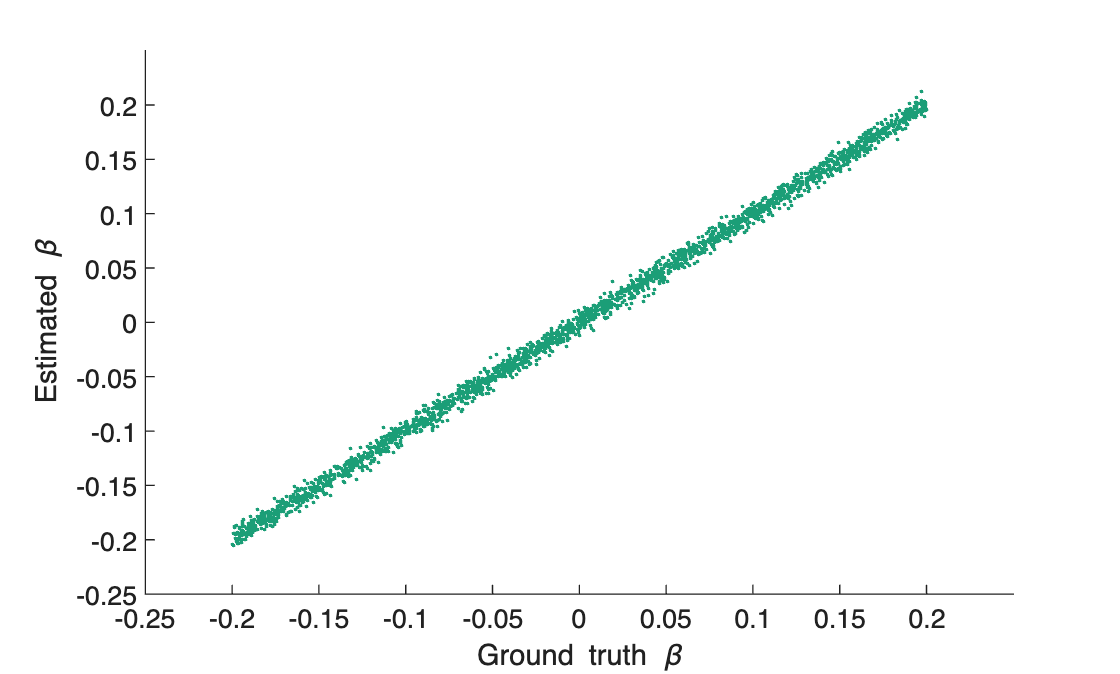

figure;
scatter(betaTrue(:), beta_hat(:), 2, [27,158,119]./255, 'filled');
xlim([-0.25 0.25]);
ylim([-0.25 0.25]);
xlabel('Ground truth \beta');
ylabel('Estimated \beta')

## Examine binning

Based on similarity of the random effects variance estiamtes, we bin the outcome using an equally spaced bin - for the outcome that are in the same bin, the parameters are estimated together using a single GLS; in this example, instead of performing 50 GLS estimation, the problem was reduced to performing 39 GLS estimations

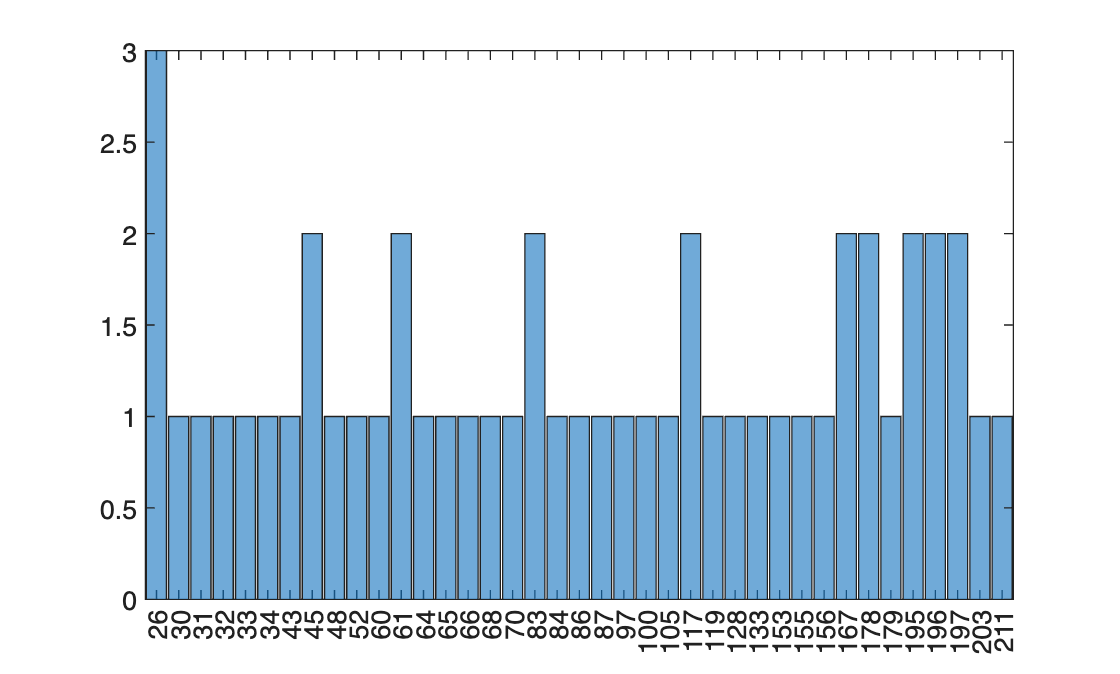

figure;
histogram(categorical(binvec_save));

## Other ways of calling `FEMA_fit`

`FEMA_fit` acceps a range of additional name-value pairs which can be used to specify additional analysis options.

### Specifying permutations

Wildbootstrap permutations can be used to genrate non-parameteric confidence interval

% Fit the model while specifying 20 permutations; the results will be in
% the *_perm variables
nperms = 20;
[beta_hat,      beta_se,        zmat,        logpmat,              ...
 sig2tvec,      sig2mat,        Hessmat,     logLikvec,            ...
 beta_hat_perm, beta_se_perm,   zmat_perm,   sig2tvec_perm,        ...
 sig2mat_perm,  logLikvec_perm, binvec_save, nvec_bins,            ...
 tvec_bins,     FamilyStruct,   coeffCovar,  reusableVars] =       ...
 FEMA_fit(X, iid, eid, fid, agevec, ymat, niter, contrasts, nbins, ...
          GRM, 'RandomEffects', RandomEffects, 'nperms', nperms);

03-Dec-2025 09:24:57 in FEMA_fit - ***Start***
FEMA 3.0.0 (2025.09.17)
ModelSingularityIndex = 1.13677
03-Dec-2025 09:24:58 in FEMA_parse_family - Parsing family structure
Elapsed time is 1.926288 seconds.
03-Dec-2025 09:25:01 in FEMA_fit - size(M) = [118546 3]
03-Dec-2025 09:25:01 in FEMA_fit - Cov_MoM:
   1.0e-04 *

    0.1340   -0.1340   -0.0000
   -0.1340    0.6632   -0.5292
   -0.0000   -0.5292    0.9292

03-Dec-2025 09:25:01 in FEMA_fit - Mi*M:
    1.0003    0.0000    0.0000
    0.0000    1.0001   -0.0000
   -0.0000   -0.0000    0.9999

03-Dec-2025 09:25:02 in FEMA_fit - permi=00/20 (1.31s - remaining Infs)
03-Dec-2025 09:25:03 in FEMA_fit - permi=01/20 (1.32s - remaining 50s)
03-Dec-2025 09:25:05 in FEMA_fit - permi=02/20 (1.34s - remaining 36s)
03-Dec-2025 09:25:06 in FEMA_fit - permi=03/20 (1.25s - remaining 30s)
03-Dec-2025 09:25:07 in FEMA_fit - permi=04/20 (1.25s - remaining 26s)
03-Dec-2025 09:25:08 in FEMA_fit - permi=05/20 (1.27s - remaining 23s)
03-Dec-2025 09:25:10 in 

### Changing the covariance type

FEMA supports two types of random effects covariance types: compound symmetry and unstructured. The default is compound symmetry (constant variance over time) but this can be switched to unstructured by passing in `CovType` parameter

% Fit the model while specifying unstructured covariance
nperms = 20;
[beta_hat,      beta_se,        zmat,        logpmat,              ...
 sig2tvec,      sig2mat,        Hessmat,     logLikvec,            ...
 beta_hat_perm, beta_se_perm,   zmat_perm,   sig2tvec_perm,        ...
 sig2mat_perm,  logLikvec_perm, binvec_save, nvec_bins,            ...
 tvec_bins,     FamilyStruct,   coeffCovar,  reusableVars] =       ...
 FEMA_fit(X, iid, eid, fid, agevec, ymat, niter, contrasts, nbins, ...
          GRM, 'RandomEffects', RandomEffects,                     ...
          'CovType', 'unstructured', 'returnReusable', true);

03-Dec-2025 09:25:27 in FEMA_fit - ***Start***
FEMA 3.0.0 (2025.09.17)
ModelSingularityIndex = 1.13677
03-Dec-2025 09:25:28 in FEMA_parse_family - Parsing family structure
Elapsed time is 1.846546 seconds.
03-Dec-2025 09:25:30 in FEMA_fit - size(M) = [118546 3]
03-Dec-2025 09:25:30 in FEMA_fit - Cov_MoM:
   1.0e-04 *

    0.1340   -0.1340   -0.0000
   -0.1340    0.6632   -0.5292
   -0.0000   -0.5292    0.9292

03-Dec-2025 09:25:30 in FEMA_fit - Mi*M:
    1.0003    0.0000    0.0000
    0.0000    1.0001   -0.0000
   -0.0000   -0.0000    0.9999

03-Dec-2025 09:25:34 in FEMA_fit - ***Done*** (6.85 seconds)

